## Importar las señales necesarias

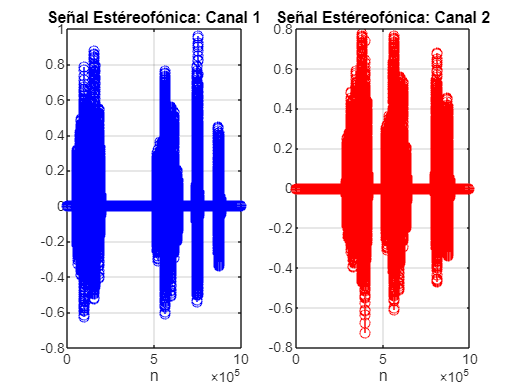

function [signal, sample_rate] = import_signal()
    % Busca el archivo que se quiere importar
    [filename, path] = uigetfile({'*.mp3;*.wav'}); 
    % figure(app.UIFigure);
    fullFileName = fullfile(path, filename);  % Construye la ruta completa del archivo
    
    % Recuperar los datos importados
    [signal, sample_rate] = audioread(fullFileName);
end

function plot_the_signal(stereo_signal)
    figure
    subplot(1,2,1); stem(stereo_signal(:,1),'b');grid on;
    title('Señal Estéreofónica: Canal 1'); xlabel('n');
    subplot(1,2,2); stem(stereo_signal(:,2),'r');grid on;
    title('Señal Estéreofónica: Canal 2'); xlabel('n');
end

[stereo_signal, sample_rate] = import_signal();

plot_the_signal(stereo_signal);


% sound(stereo_signal, sample_rate);

% pause(20);

## Preprocesamiento señal importada

preprocessed_signal = preprocesamiento(stereo_signal, 'Between -1 y 1');

You are using the normalize function -1 to 1


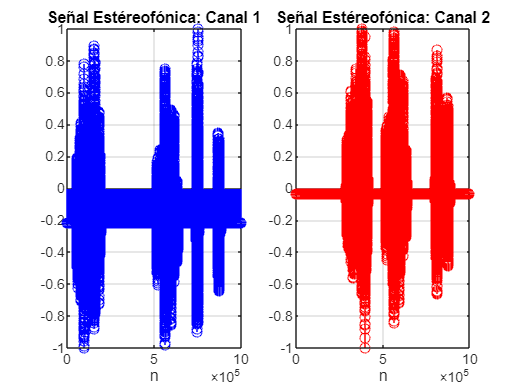


plot_the_signal(preprocessed_signal);


% sound(preprocessed_signal, sample_rate);

## Procesamiento

[signal, sample_rate] = procesamiento_en_el_tiempo('desplazar');

plot_the_signal(signal);

sound(stereo_signal, sample_rate);

## Generar señales

clc; clear vars;

disp('Se seleccionó la Seno');

Se seleccionó la Seno


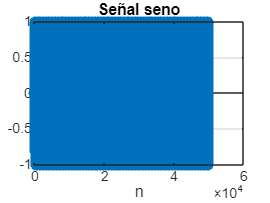

dlgtitle = 'Sine Signal Parameters';
prompt = {'Ganancia:','Frecuencia Análoga:','Frecuencia Muestreo:', 'Fase (rad)' ,'Desplazamiento:','n_inicio:','n_final:' };
dims = [1 35];
defect_input = {'1','100','44100','0','0', '0', '50000'};
answer = inputdlg(prompt, dlgtitle, dims, defect_input);

A=str2num(answer{1}); % Ganancia de la exponencial
Fa=str2num(answer{2}); % Frecuencia análoga
Fs=str2num(answer{3}); % Frecuencia de muestreo

Fase=str2num(answer{4}); % Fase de la señal análoga (Rad)

n0=str2num(answer{5});
ni=str2num(answer{6});
nf=str2num(answer{7});

% disp(answer{1});
% disp(answer{6});

Ts=1/Fs; %Periodo de muestreo

n6=ni:nf; %Instantes de tiempo

t = n6*Ts; % Time vector en segundos dependiente del tiempo de muestreo

variable = (2*pi*Fa*(n6-n0)/Fs+ Fase);
result = 2*pi*Fa/Fs+ Fase;
x = A*[sin(2*pi*Fa*t + Fase)]; %/(2*pi*Fa*(-55)/Fs+ Fase);

sample_rate = Fs;

figure;
stem(n6,x);
% xlabel('n'); ylabel('x(n)'); title(['Señal Senoidal, Fa=' num2str(Fa) ' Fs= ' num2str(Fs)]);grid on
title('Señal seno');
xlabel('n');
grid('on');


sound(x, sample_rate);

pause(5);

transposed_signal = x.';

preprocessed_signal = preprocesamiento(transposed_signal, 'Between -1 y 1');

You are using the normalize function -1 to 1




figure;
stem(n6, preprocessed_signal);
% xlabel('n'); ylabel('x(n)'); title(['Señal Senoidal, Fa=' num2str(Fa) ' Fs= ' num2str(Fs)]);grid on
title('Señal seno');
xlabel('n');
grid('on');


sound(preprocessed_signal, sample_rate);


## Suma de señales

function [prosig,prosigFs] = adicionButtonPushed(Fs1,Fs2,signal1,signal2)

%%%% Se deben obtener los valores de la señal seleccionada

    
            if Fs2<Fs1
                nf = interpolacionfrecuencial(Fs1,signal1,Fs2); %señal cambiada
                newfreq = transpose(nf);
                lnf = length(newfreq);
                lns2 = length(signal2);
                prosigFs = Fs2;
                if lnf>lns2
                    lnss = lnf-lns2;
                    signal2 = [signal2 zeros(1,lnss)];
                    
                else
                     lnss = lns2-lnf;
                    newfreq = [newfreq zeros(1,lnss)];
                    
                end
                prosig = signal2 + newfreq; 
            else
                nf = interpolacionfrecuencial(Fs2,signal2,Fs1); %señal cambiada
                newfreq = transpose(nf);
                lnf = length(newfreq);
                lns1 = length(signal1);
                prosigFs = Fs1;
                if lnf>lns1
                    lnss = lnf-lns1;
                    signal1 = [signal1 zeros(1,lnss)];
                    
                else
                     lnss = lns1-lnf;
                    newfreq = [newfreq zeros(1,lnss)];
                    
                end
             
                prosig = signal1 + newfreq;
            end
          disp(size(prosig))


end

function graficar(axes, specific_title, signal)
    number_of_points = (1:length(signal));
    stem(axes, number_of_points, signal);
    title(axes, specific_title);
    xlabel(axes, 'n');
    grid(axes, 'on');
end


% Fs1 = 44100;
% Fs2 = 44100;
% signal1 = (1*[zeros(1,abs(0)+0)  ones(1, abs(50000)+1-0)]).';
% graficar(axes, 'signal 1', signal1);
% n3=0:50000;
% signal2 = (1*(n3)).';
% graficar(axes, 'signal 2', signal2);
% [prosig,prosigFs] = adicionButtonPushed(Fs1,Fs2,signal1,signal2);
% graficar(axes, 'seh', prosig);



## Uso con la DAC

% Button pushed function: DAQButton
function DAQButtonPushed(app, event)
    % Reset the DAQ devices configuration
    daqreset;
    dev = daqlist; % Get the list of connected DAQ devices

    % Check if there is no DAQ device connected
    if isempty(dev)
        f = msgbox("No DAQ connected. Please try again.", "Error", "warn");
        return; % Exit if no devices are found
    else
        Devices = table2array(dev(:,3));
        numDev = table2array(dev(:,2));
        vendor = table2array(dev(:,1));
        [indx,tf] = listdlg('PromptString', 'Select a device:','SelectionMode', 'single','ListString', Devices);
    end

    % Proceed if a device was selected
    if tf
        selectedVendor = vendor{indx};
        % Check for device vendor
        if strcmp(selectedVendor, "digilent")
            f = msgbox("Unsupported device vendor: digilent", "Warning", "warn");

        elseif strcmp(selectedVendor, "ni")
            % Open input dialog to ask user for port number and time duration
            prompt = {'Enter the port (e.g., ai0):','Enter the capture time (s):'};
            dlgtitle = 'DAQ Data Configuration';
            dims = [1 35];
            definput = {'ai0','10'};
            answer = inputdlg(prompt, dlgtitle, dims, definput);

            % Validate user input
            if isempty(answer)
                disp('Operation cancelled by user.');
                return;
            end
            port = answer{1};
            captureTime = str2double(answer{2});
            if isnan(captureTime) || captureTime <= 0
                errordlg('Please enter a valid capture time.');
                return;
            end

            % Configure the DAQ device
            d = daq(selectedVendor);
            d.Rate = app.SampleNumberEditField.Value; % Assume this value is set correctly in the app
            % Note: 'app.fs' seems to be unused, consider removing it if not needed

            % Add input channel
            nidevice = addinput(d, numDev{indx}, port, "Voltage");
            nidevice.TerminalConfig = "SingleEnded";

            % Start reading the data
            data = read(d, seconds(captureTime));

            %% NOTE: Assumes 'app.Switch' is a UI element that determines the plot target
            switch app.Switch.Value
                case 'Input 1'
                    app.fs1 = d.Rate;
                    app.inx1 = data.Time';
                    app.iny1 = data.Variables';
                    stem(app.input1, app.inx1, app.iny1);
                    title(app.input1, 'Input 1 Data');
                    xlabel(app.input1, 'Time (s)');
                    ylabel(app.input1, 'Voltage (V)');
                case 'Input 2'
                    app.fs2 = d.Rate;
                    app.inx2 = data.Time';
                    app.iny2 = data.Variables';
                    stem(app.input2, app.inx2, app.iny2);
                    title(app.input2, 'Input 2 Data');
                    xlabel(app.input2, 'Time (s)');
                    ylabel(app.input2, 'Voltage (V)');
            end
        end
    end
end